


% 读取数据文件
filename = './2025.10.1 test/incremental_regression_test_5.log';
fid = fopen(filename, 'r');

% 跳过注释行
fgetl(fid);

% 读取cycle数量
cycle = str2double(fgetl(fid));

% 读取各数据行
total_length = str2num(fgetl(fid));
ave_sync_length = str2num(fgetl(fid));
sync_net_number = str2num(fgetl(fid));
failed_net = str2num(fgetl(fid));
reg_monopoliezd = str2num(fgetl(fid));
reg_mixed = str2num(fgetl(fid));

fclose(fid);

% 创建时间轴
time = 1:cycle;

% 创建大画布
figure('Position', [100, 100, 1200, 1200]);

% 第一张图：failed_net（原第一张图的剩余部分）
subplot(3, 1, 1);
hold on;

% 绘制failed_net原始数据
plot(time, failed_net, 'g-', 'LineWidth', 1.5, 'DisplayName', 'failed\_net');
plot(time, ave_sync_length, 'r-', 'LineWidth', 1.5, 'DisplayName', 'ave\_sync\_length');

% 计算并绘制平均值
avg_failed_net = mean(failed_net);
avg_ave_sync_length = mean(ave_sync_length);
yline(avg_failed_net, 'g--', 'LineWidth', 1, 'DisplayName', sprintf('avg failed\\_net = %.2f', avg_failed_net));
yline(avg_ave_sync_length, 'r--', 'LineWidth', 1, 'DisplayName', sprintf('avg ave\\_sync\\_length = %.2f', avg_ave_sync_length));

xlabel('Cycle');
ylabel('Values');
title('Analysis of failed\_net and ave\_sync\_length');
legend('Location', 'east');
grid on;
hold off;

% 第二张图：reg_monopoliezd, reg_mixed（保持不变）
subplot(3, 1, 2);
hold on;

% 绘制原始数据
plot(time, reg_monopoliezd, 'm-', 'LineWidth', 1.5, 'DisplayName', 'reg\_monopoliezd');
plot(time, reg_mixed, 'c-', 'LineWidth', 1.5, 'DisplayName', 'reg\_mixed');

% 计算并绘制平均值
avg_reg_monopoliezd = mean(reg_monopoliezd);
avg_reg_mixed = mean(reg_mixed);

yline(avg_reg_monopoliezd, 'm--', 'LineWidth', 1, 'DisplayName', sprintf('avg reg\\_monopoliezd = %.4f', avg_reg_monopoliezd));
yline(avg_reg_mixed, 'c--', 'LineWidth', 1, 'DisplayName', sprintf('avg reg\\_mixed = %.4f', avg_reg_mixed));

xlabel('Cycle');
ylabel('Values');
title('Analysis of reg\_monopoliezd and reg\_mixed');
legend('Location', 'east');
grid on;
hold off;

% 第三张图：total_length, ave_sync_length（新增子图）
subplot(3, 1, 3);
hold on;

% 绘制原始数据
plot(time, total_length, 'b-', 'LineWidth', 1.5, 'DisplayName', 'total\_length');


% 计算并绘制平均值
avg_total_length = mean(total_length);
yline(avg_total_length, 'b--', 'LineWidth', 1, 'DisplayName', sprintf('avg total\\_length = %.2f', avg_total_length));


xlabel('Cycle');
ylabel('Values');
title('Analysis of total\_length');
legend('Location', 'best');
grid on;
hold off;

% 显示统计信息
fprintf('=== 数据统计信息 ===\n');

=== 数据统计信息 ===


fprintf('总周期数: %d\n', cycle);

总周期数: 30


fprintf('\n数据统计:\n');


数据统计:


fprintf('total_length - 平均值: %.4f, 标准差: %.4f, 范围: [%d, %d]\n', ...
    mean(total_length), std(total_length), min(total_length), max(total_length));

total_length - 平均值: 685.2333, 标准差: 4.8258, 范围: [684, 708]


fprintf('ave_sync_length - 平均值: %.4f, 标准差: %.4f, 范围: [%.4f, %.4f]\n', ...
    mean(ave_sync_length), std(ave_sync_length), min(ave_sync_length), max(ave_sync_length));

ave_sync_length - 平均值: 8.5421, 标准差: 0.0636, 范围: [8.5263, 8.8421]


fprintf('failed_net - 平均值: %.4f, 标准差: %.4f, 范围: [%d, %d]\n', ...
    mean(failed_net), std(failed_net), min(failed_net), max(failed_net));

failed_net - 平均值: 4.0000, 标准差: 0.0000, 范围: [4, 4]



fprintf('\n第二组数据统计:\n');


第二组数据统计:


fprintf('reg_monopoliezd - 平均值: %.6f, 标准差: %.6f, 范围: [%.6f, %.6f]\n', ...
    mean(reg_monopoliezd), std(reg_monopoliezd), min(reg_monopoliezd), max(reg_monopoliezd));

reg_monopoliezd - 平均值: 0.849220, 标准差: 0.015626, 范围: [0.816742, 0.887387]


fprintf('reg_mixed - 平均值: %.6f, 标准差: %.6f, 范围: [%.6f, %.6f]\n', ...
    mean(reg_mixed), std(reg_mixed), min(reg_mixed), max(reg_mixed));

reg_mixed - 平均值: 0.150780, 标准差: 0.015626, 范围: [0.112613, 0.183258]


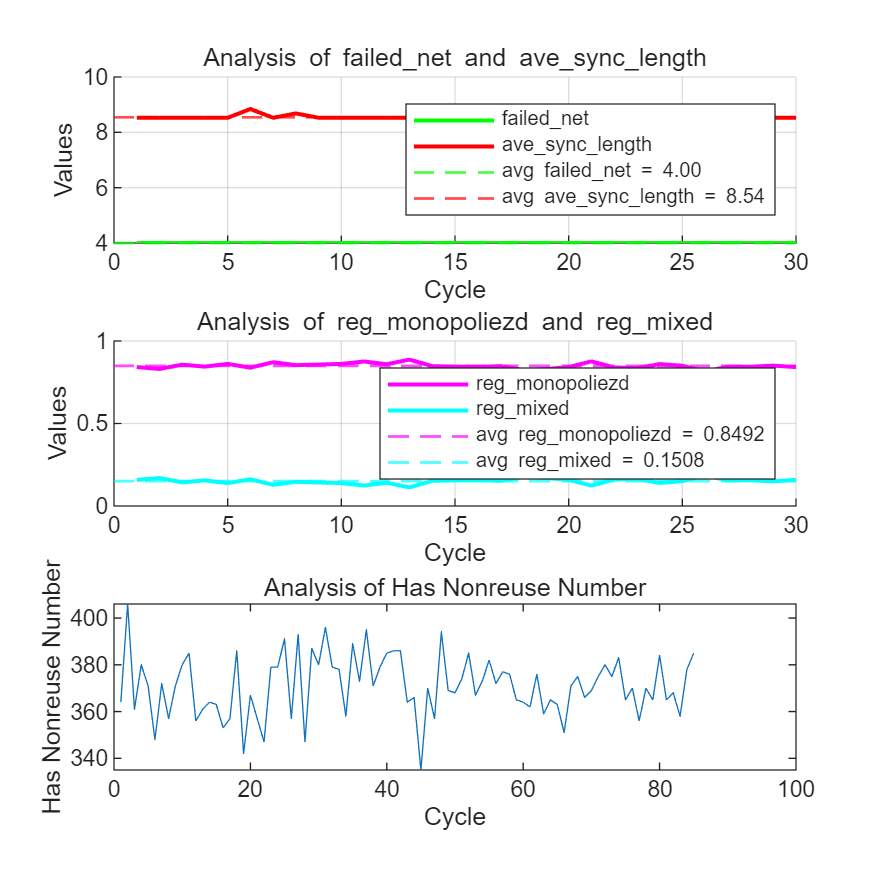

y1 = [364, 406, 361, 403, 380, 371, 348, 372, 357, 371, 380, 385, 356, 361, 364, 363, 353, 357, 386, 342, 367, 357, 347, 432, 379, 379, 391, 357, 393, 347, 387, 380, 396, 379, 378, 358, 389, 373, 395, 371, 379, 385, 386, 386, 364, 366, 335, 370, 357, 394, 369, 368, 374, 385, 409, 367, 373, 382, 372, 377, 414, 419, 376, 365, 364, 362, 414, 376, 411, 418, 359, 365, 407, 363, 351, 371, 375, 425, 366, 369, 375, 380, 275, 383, 365, 370, 356, 370, 365, 384, 365, 368, 358, 417, 378, 422, 421, 385, ];
y2 = [364, 406, 361, 380, 371, 348, 372, 357, 371, 380, 385, 356, 361, 364, 363, 353, 357, 386, 342, 367, 357, 347, 379, 379, 391, 357, 393, 347, 387, 380, 396, 379, 378, 358, 389, 373, 395, 371, 379, 385, 386, 386, 364, 366, 335, 370, 357, 394, 369, 368, 374, 385, 367, 373, 382, 372, 377, 376, 365, 364, 362, 376, 359, 365, 363, 351, 371, 375, 366, 369, 375, 380, 375, 383, 365, 370, 356, 370, 365, 384, 365, 368, 358, 378, 385];
x = 1:1:length(y2);
plot(x, y2)
title("Analysis of Has Nonreuse Number")
xlabel("Cycle")
ylabel("Has Nonreuse Number")

% 数据定义
model1_nonreuse = [186, 228, 204, 220, 227, 222, 212, 216, 208, 223, 201, 223, 235, 211, 225, 215, 239, 186, 251, 239];
model2_nonreuse = [260, 234, 218, 201, 239, 199, 229, 205, 200, 199, 232, 186, 213, 245, 222, 202, 234, 206, 209, 213];
different_regs = [451, 591, 482, 473, 542, 444, 489, 670, 451, 468, 472, 432, 452, 427, 467, 449, 420, 459, 443, 447];

% 确保数据为列向量
model1_nonreuse = model1_nonreuse(:);
model2_nonreuse = model2_nonreuse(:);
different_regs = different_regs(:);

fprintf('=== 线性相关性分析 ===\n\n');

=== 线性相关性分析 ===




%% 1. 直接相关性分析
fprintf('1. 直接相关性分析:\n');

1. 直接相关性分析:


fprintf('----------------------------------------\n');

----------------------------------------



% model1_nonreuse 与 different_regs 的相关性
[r1, p1] = corr(model1_nonreuse, different_regs);
fprintf('model1_nonreuse 与 different_regs:\n');

model1_nonreuse 与 different_regs:


fprintf('相关系数 r = %.4f, p值 = %.4f\n', r1, p1);

相关系数 r = -0.0243, p值 = 0.9189



% model2_nonreuse 与 different_regs 的相关性
[r2, p2] = corr(model2_nonreuse, different_regs);
fprintf('model2_nonreuse 与 different_regs:\n');

model2_nonreuse 与 different_regs:


fprintf('相关系数 r = %.4f, p值 = %.4f\n\n', r2, p2);

相关系数 r = 0.0627, p值 = 0.7929




%% 2. 数字组合与 different_regs 的相关性
fprintf('2. 数字组合与 different_regs 的相关性:\n');

2. 数字组合与 different_regs 的相关性:


fprintf('----------------------------------------\n');

----------------------------------------



% 定义各种组合
combinations = {
    model1_nonreuse + model2_nonreuse, '相加 (model1 + model2)';
    model1_nonreuse - model2_nonreuse, '相减 (model1 - model2)';
    model2_nonreuse - model1_nonreuse, '相减 (model2 - model1)';
    (model1_nonreuse + model2_nonreuse)/2, '平均值';
    model1_nonreuse .* model2_nonreuse, '相乘';
    model1_nonreuse ./ model2_nonreuse, '相除 (model1/model2)';
    abs(model1_nonreuse - model2_nonreuse), '绝对差值';
    sqrt(model1_nonreuse.^2 + model2_nonreuse.^2), '平方和开根';
};

% 计算每种组合与 different_regs 的相关性
results = [];
for i = 1:size(combinations, 1)
    combination_data = combinations{i, 1};
    combination_name = combinations{i, 2};
    
    [r, p] = corr(combination_data, different_regs);
    
    fprintf('%s:\n', combination_name);
    fprintf('  相关系数 r = %.4f, p值 = %.4f\n', r, p);
    
    % 存储结果
    results(i).name = combination_name;
    results(i).r = r;
    results(i).p = p;
end

相加 (model1 + model2):


  相关系数 r = 0.0351, p值 = 0.8832


相减 (model1 - model2):


  相关系数 r = -0.0572, p值 = 0.8108


相减 (model2 - model1):


  相关系数 r = 0.0572, p值 = 0.8108


平均值:


  相关系数 r = 0.0351, p值 = 0.8832


相乘:


  相关系数 r = 0.0486, p值 = 0.8387


相除 (model1/model2):


  相关系数 r = -0.0826, p值 = 0.7291


绝对差值:


  相关系数 r = -0.3420, p值 = 0.1400


平方和开根:


  相关系数 r = 0.0195, p值 = 0.9350



%% 3. 显著性检验和结果排序
fprintf('\n3. 相关性强度排序 (按绝对值):\n');


3. 相关性强度排序 (按绝对值):


fprintf('----------------------------------------\n');

----------------------------------------



% 按相关系数绝对值排序
[~, sorted_idx] = sort(abs([results.r]), 'descend');

for i = 1:length(sorted_idx)
    idx = sorted_idx(i);
    significance = '';
    if results(idx).p < 0.05
        significance = '** 显著 **';
    elseif results(idx).p < 0.1
        significance = '* 边缘显著 *';
    end
    
    fprintf('%2d. %s: r = %7.4f, p = %6.4f %s\n', ...
        i, results(idx).name, results(idx).r, results(idx).p, significance);
end

 1. 绝对差值: r = -0.3420, p = 0.1400 
 2. 相除 (model1/model2): r = -0.0826, p = 0.7291 
 3. 相减 (model1 - model2): r = -0.0572, p = 0.8108 
 4. 相减 (model2 - model1): r =  0.0572, p = 0.8108 
 5. 相乘: r =  0.0486, p = 0.8387 
 6. 相加 (model1 + model2): r =  0.0351, p = 0.8832 
 7. 平均值: r =  0.0351, p = 0.8832 
 8. 平方和开根: r =  0.0195, p = 0.9350 


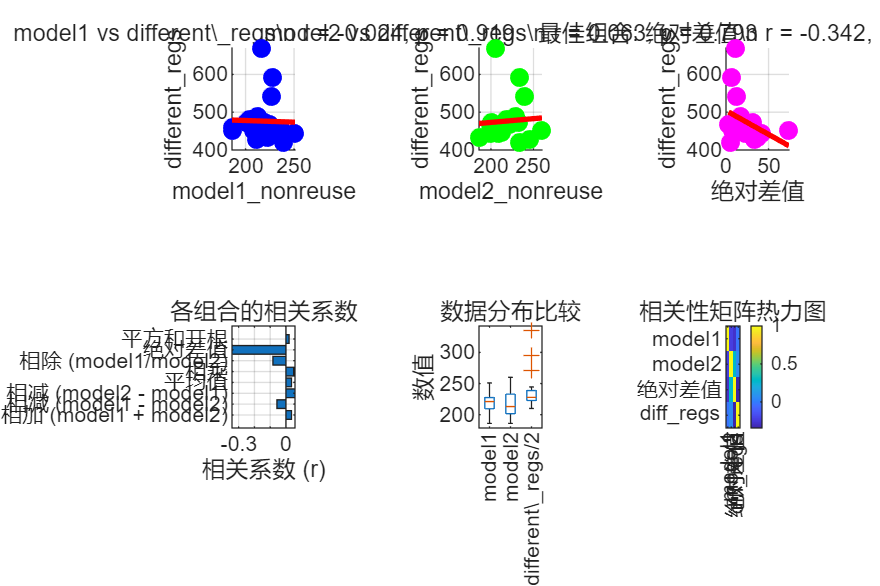


%% 4. 可视化分析
figure('Position', [100, 100, 1200, 800]);

% 子图1: 直接相关性散点图
subplot(2, 3, 1);
scatter(model1_nonreuse, different_regs, 50, 'filled', 'b');
hold on;
p = polyfit(model1_nonreuse, different_regs, 1);
yfit = polyval(p, model1_nonreuse);
plot(model1_nonreuse, yfit, 'r-', 'LineWidth', 2);
xlabel('model1\_nonreuse');
ylabel('different\_regs');
title(sprintf('model1 vs different\\_regs\\n r = %.3f, p = %.3f', r1, p1));
grid on;

subplot(2, 3, 2);
scatter(model2_nonreuse, different_regs, 50, 'filled', 'g');
hold on;
p = polyfit(model2_nonreuse, different_regs, 1);
yfit = polyval(p, model2_nonreuse);
plot(model2_nonreuse, yfit, 'r-', 'LineWidth', 2);
xlabel('model2\_nonreuse');
ylabel('different\_regs');
title(sprintf('model2 vs different\\_regs\\n r = %.3f, p = %.3f', r2, p2));
grid on;

% 子图3: 最佳组合的相关性
best_idx = sorted_idx(1);
best_combination = combinations{best_idx, 1};
best_name = combinations{best_idx, 2};

subplot(2, 3, 3);
scatter(best_combination, different_regs, 50, 'filled', 'm');
hold on;
p = polyfit(best_combination, different_regs, 1);
yfit = polyval(p, best_combination);
plot(best_combination, yfit, 'r-', 'LineWidth', 2);
xlabel(best_name);
ylabel('different\_regs');
title(sprintf('最佳组合: %s\\n r = %.3f, p = %.3f', best_name, results(best_idx).r, results(best_idx).p));
grid on;

% 子图4: 相关系数条形图
subplot(2, 3, 4);
r_values = [results.r];
barh(r_values);
set(gca, 'YTickLabel', {results.name});
xlabel('相关系数 (r)');
title('各组合的相关系数');
grid on;

% 子图5: 数据分布
subplot(2, 3, 5);
boxplot([model1_nonreuse, model2_nonreuse, different_regs/2], ...
    'Labels', {'model1', 'model2', 'different\_regs/2'});
ylabel('数值');
title('数据分布比较');

% 子图6: 热力图显示相关性矩阵
subplot(2, 3, 6);
correlation_matrix = corr([model1_nonreuse, model2_nonreuse, ...
    best_combination, different_regs]);
imagesc(correlation_matrix);
colorbar;
set(gca, 'XTick', 1:4, 'XTickLabel', {'model1', 'model2', best_name, 'diff\_regs'});
set(gca, 'YTick', 1:4, 'YTickLabel', {'model1', 'model2', best_name, 'diff\_regs'});
title('相关性矩阵热力图');


%% 5. 线性回归分析
fprintf('\n4. 线性回归分析 (最佳组合):\n');


4. 线性回归分析 (最佳组合):


fprintf('----------------------------------------\n');

----------------------------------------



X = [ones(size(best_combination)), best_combination]; % 添加常数项
[b, bint, r, rint, stats] = regress(different_regs, X);

fprintf('回归方程: different_regs = %.2f + %.2f * %s\n', b(1), b(2), best_name);

回归方程: different_regs = 504.21 + -1.26 * 绝对差值


fprintf('R² = %.4f, F统计量 = %.4f, p值 = %.4f\n', stats(1), stats(2), stats(3));

R² = 0.1169, F统计量 = 2.3837, p值 = 0.1400


fprintf('系数95%%置信区间: [%.4f, %.4f]\n', bint(2,1), bint(2,2));

系数95%置信区间: [-2.9720, 0.4542]



%% 6. 输出总结
fprintf('\n5. 分析总结:\n');


5. 分析总结:


fprintf('----------------------------------------\n');

----------------------------------------


fprintf('样本数量: %d\n', length(model1_nonreuse));

样本数量: 20


fprintf('model1_nonreuse 均值: %.2f ± %.2f\n', mean(model1_nonreuse), std(model1_nonreuse));

model1_nonreuse 均值: 218.55 ± 16.68


fprintf('model2_nonreuse 均值: %.2f ± %.2f\n', mean(model2_nonreuse), std(model2_nonreuse));

model2_nonreuse 均值: 217.30 ± 18.96


fprintf('different_regs 均值: %.2f ± %.2f\n', mean(different_regs), std(different_regs));

different_regs 均值: 476.45 ± 60.20



% 判断相关性强度
best_r = results(best_idx).r;
if abs(best_r) >= 0.7
    strength = '强';
elseif abs(best_r) >= 0.5
    strength = '中等';
elseif abs(best_r) >= 0.3
    strength = '弱';
else
    strength = '很弱';
end

fprintf('\n最佳相关性: %s (%s相关性)\n', best_name, strength);


最佳相关性: 绝对差值 (弱相关性)
